# Varying M1

clear
clc

pa = 7e4; %ambient pressure
Ta = 210; %ambient temperature
Mf = linspace(1.8,12,100); %free stream mach number
Shock = 1.1; %normal shock strength (before shock mach number)
Mbe = 0.2; %burner entry mach number
Tb = 1700; %maximum burner temperature
bpr = 1; %burner pressure ratio
epr = 1; %exhaust pressure ratio
thrust = 5e5; %required thrust

for i = 1 : length(Mf)
    [A1(i), At1(i), Abe(i), Abx(i), At3(i), Ae(i), thermeff(i), propeff(i)] = ramjet(pa,Ta,Mf(i),Shock,Mbe,Tb,bpr,epr,thrust);
end

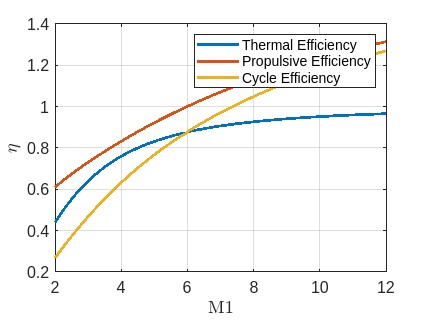

% efficiencies
figure(1)
plot(Mf,thermeff,'LineWidth',2)
hold on
plot(Mf,propeff,'LineWidth',2)
plot(Mf,propeff.*thermeff,'LineWidth',2)
hold off
grid on
xlabel('M1','Interpreter','latex')
ylabel('$\eta$','Interpreter','latex')
legend('Thermal Efficiency','Propulsive Efficiency','Cycle Efficiency')
set(gca,'FontSize',12)

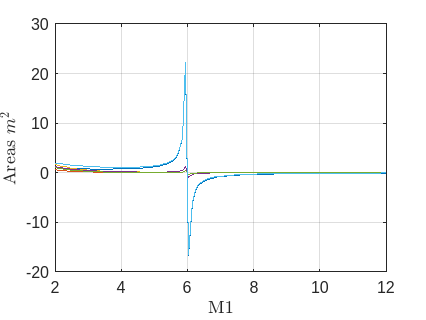


% Areas
figure(2)
plot(Mf,A1)
hold on
plot(Mf,At1)
plot(Mf,Abe)
plot(Mf,Abx)
plot(Mf,At3)
plot(Mf,Ae)
hold off
grid on
xlabel('M1','Interpreter','latex')
ylabel('Areas $m^2$','Interpreter','latex')
set(gca,'FontSize',12)